# VectorField.csv 可視化ツール

列 : PosX, PosY, PosZ, NormVecX, NormVecY, NormVecZ, Value, IsRightHand

Valueの単位はdB

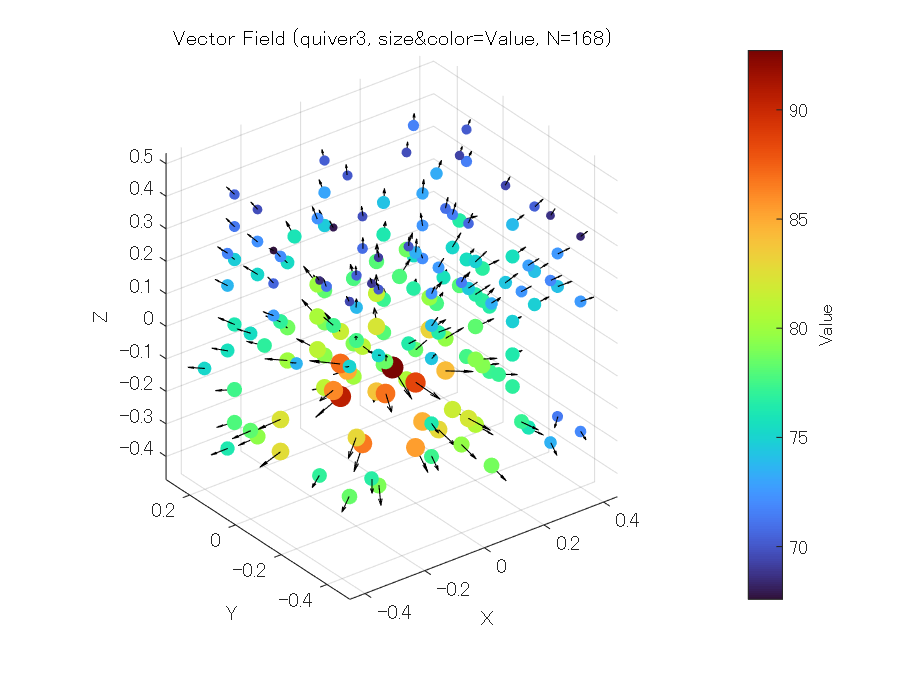

%% ==== 可変パラメータ設定 ====
markerSizeMin = 1;     % マーカーサイズ最小
markerSizeMax = 100;     % マーカーサイズ最大
colormapType  = 'turbo'; % カラーマップ種類（例: 'parula', 'jet', 'turbo', 'hot'）

maxPoints = 200;         % 最大矢印数
percentileThreshold = 0; % 上位パーセンタイル（高強度優先）

arrowLengthMin = 0.01;    % 矢印長さ最小スケール
arrowLengthMax = 0.1;    % 矢印長さ最大スケール
%% ==========================

%% CSV読み込み
fname = 'csv/VectorFieldSample_Grid.csv';
T = readtable(fname);
T.Properties.VariableNames = strtrim(T.Properties.VariableNames);

% 列取り出し
xv = T.PosX;     yv = T.PosY;     zv = T.PosZ;
uv = T.NormVecX; vv = T.NormVecY; wv = T.NormVecZ;
val = T.Value;
irh = T.IsRightHand;

% 左手系補正（Z軸反転）
flipMask = (irh == 0);
zv(flipMask) = -zv(flipMask);
wv(flipMask) = -wv(flipMask);

%% 表示点を間引き（高強度優先）
thr = prctile(val, percentileThreshold);
candIdx = find(val >= thr);
[~, order] = sort(val(candIdx), 'descend');
candIdx = candIdx(order);
if numel(candIdx) > maxPoints
    step = ceil(numel(candIdx)/maxPoints);
    seedIdx = candIdx(1:step:end);
else
    seedIdx = candIdx;
end

%% ==== 全データの Value 範囲で正規化 ====
valMinAll = min(val);
valMaxAll = max(val);
valScaledAll = (val(seedIdx) - valMinAll) / (valMaxAll - valMinAll + eps);

% 矢印長さ・マーカーサイズを Value から計算
lenScale   = arrowLengthMin + (arrowLengthMax - arrowLengthMin) * valScaledAll;
markerSize = markerSizeMin  + (markerSizeMax  - markerSizeMin)  * valScaledAll;

% 矢印ベクトル
uDraw = uv(seedIdx) .* lenScale;
vDraw = vv(seedIdx) .* lenScale;
wDraw = wv(seedIdx) .* lenScale;

%% プロット
figure('Color','w');
hold on;
% 矢印（方向＋長さ）
quiver3(xv(seedIdx), yv(seedIdx), zv(seedIdx), uDraw, vDraw, wDraw, 0, 'k');
% 色と大きさをscatter3で表現
scatter3(xv(seedIdx), yv(seedIdx), zv(seedIdx), ...
         markerSize, ...             % マーカーサイズ
         val(seedIdx), 'filled');    % 色（Valueで変化）

colormap(colormapType);
cb = colorbar; cb.Label.String = 'Value';
axis equal; grid on;
xlabel('X'); ylabel('Y'); zlabel('Z');
title(sprintf('Vector Field (quiver3, size&color=Value, N=%d)', numel(seedIdx)));
view(3);